%  Set up directories
% Folder where images are stored
%     im_dir= 'D:\Emi\Saleem lab project\Animal 11\Immuno\Tiff\Slide 4 immuno\subtact_debris';
    im_dir='C:\Users\emiuc\OneDrive\Desktop\Code test\Separate channels\Edited\Subtract debris';

% Filenames
    filename_red=['Slide4_scene_1_red_edit' '.tif'];
    filename_farred=['Slide4_scene_1_farred_edit' '.tif'];
    
% Output filenames
    output_filename_red='Slide4_scene_1_red_binary.tif';
    output_filename_farred='Slide4_scene_1_farred_binary.tif';


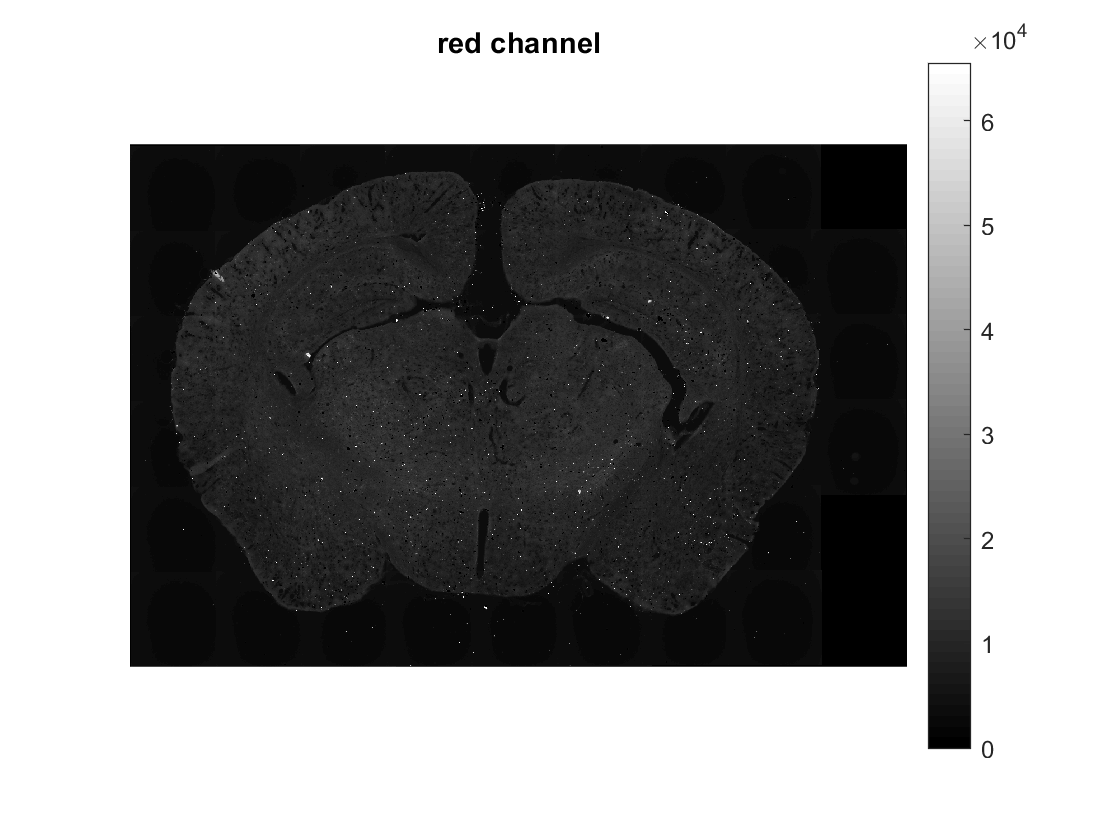


% Load red channel image
    InfoImage.red=imfinfo([im_dir filesep filename_red]);
    im_red=zeros(InfoImage.red.Height,InfoImage.red.Width,length(InfoImage.red),'double');

    TifLink = Tiff([im_dir filesep filename_red], 'r');
    for i=1:length(InfoImage.red)
       TifLink.setDirectory(i);
       im_red(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(98);
    imagesc(im_red)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('red channel')

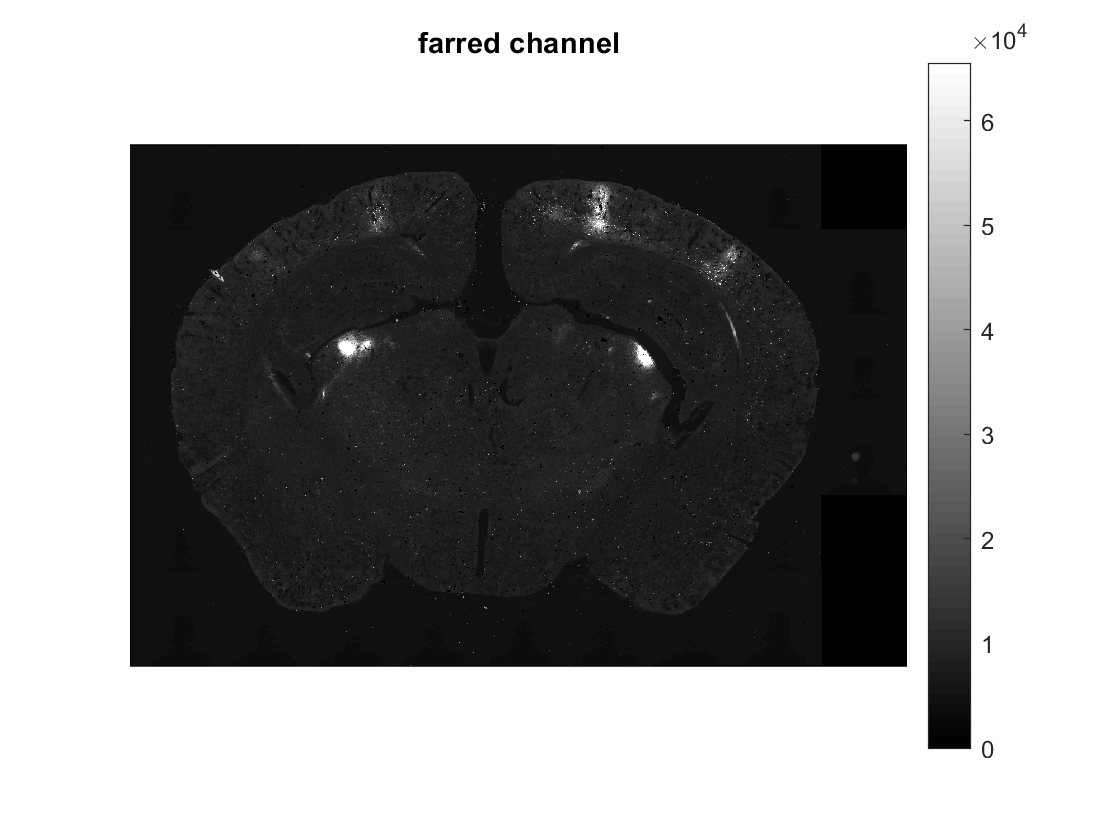

    
% Load far red channel image
    InfoImage.farred=imfinfo([im_dir filesep filename_farred]);
    im_farred=zeros(InfoImage.farred.Height,InfoImage.farred.Width,length(InfoImage.farred),'double');

    TifLink = Tiff([im_dir filesep filename_farred], 'r');
    for i=1:length(InfoImage.farred)
       TifLink.setDirectory(i);
       im_farred(:,:,i)=TifLink.read();
    end
    TifLink.close();

    figure(99);
    imagesc(im_farred)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('farred channel')

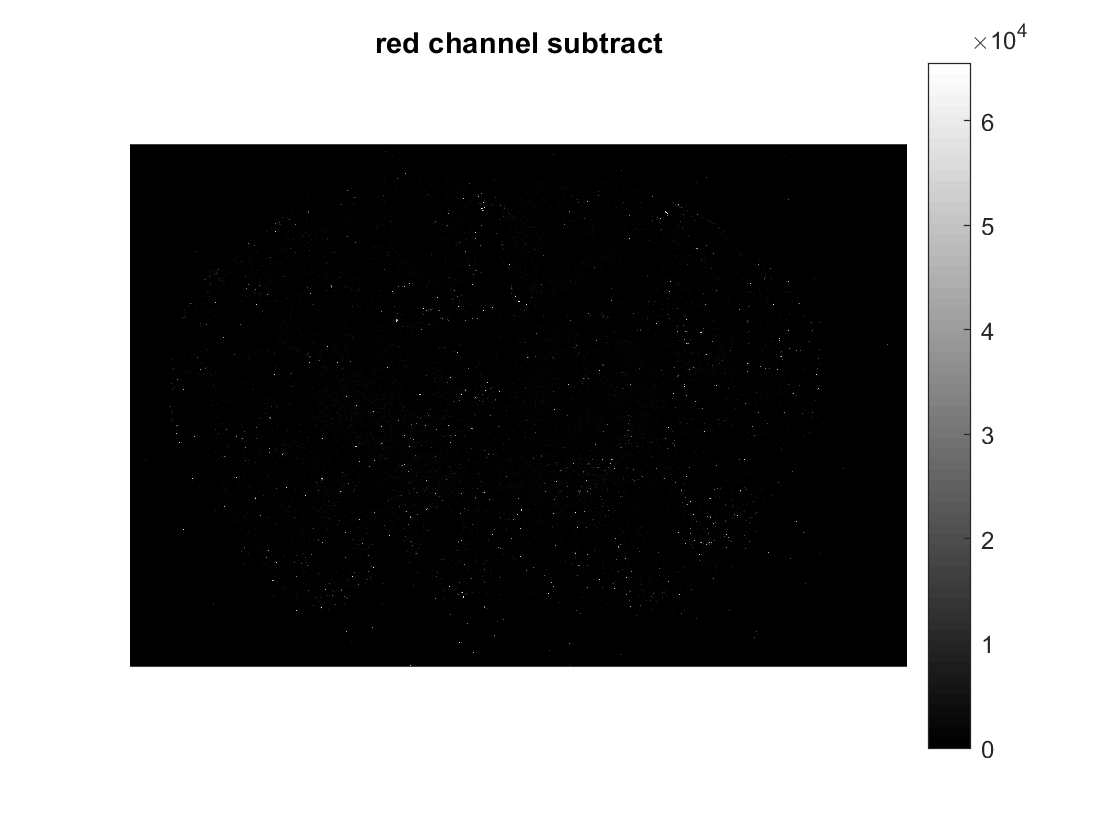

% Background subtraction 
I1 = im_red;
I2 = im_farred;

im_red_subtract = imtophat(I1,strel('disk',5));
im_farred_subtract = imtophat(I2,strel('disk',5));

    figure(100);
    imagesc(im_red_subtract)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('red channel subtract')

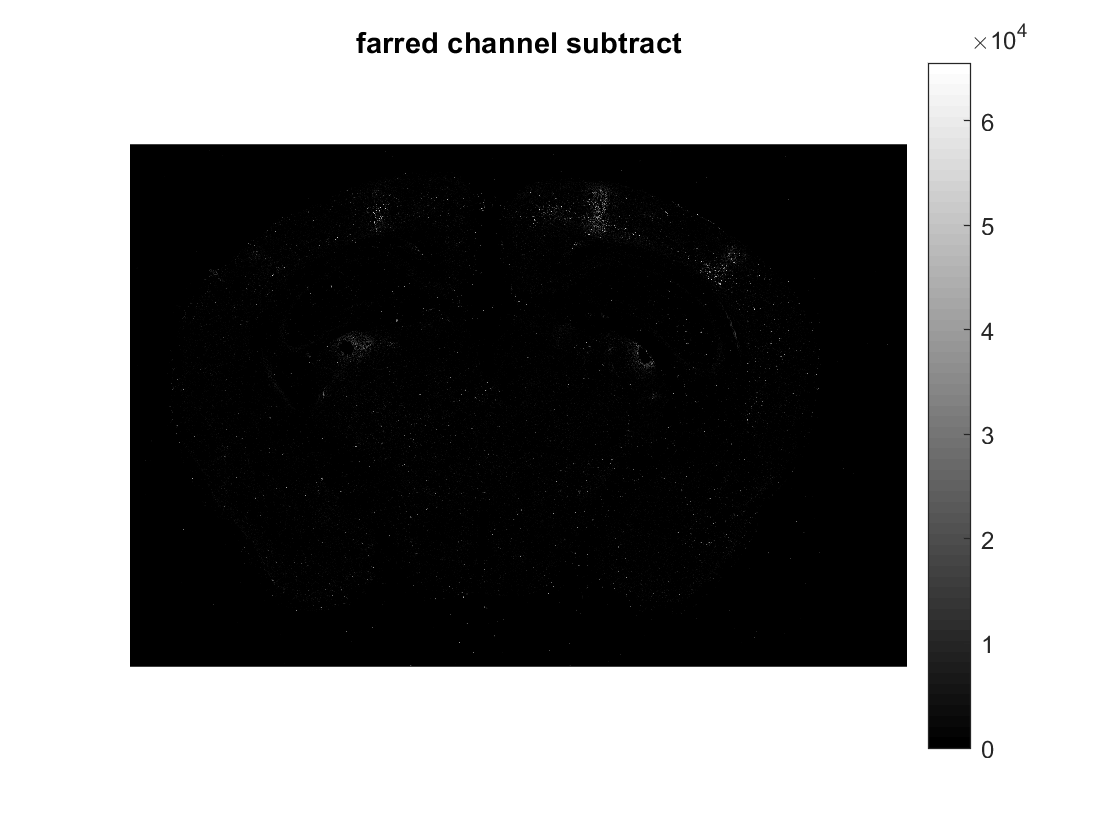

    
    figure(101);
    imagesc(im_farred_subtract)
    colormap gray; 
    colorbar
    axis off; axis equal
    title('farred channel subtract')

 

% % Thresholding
 T1=adaptthresh(im_red_subtract,0.4,'ForegroundPolarity',"bright");
 T2=adaptthresh(im_farred_subtract,0.4,'ForegroundPolarity',"bright");
 
 % Binarize
 im_red_binary=imbinarize(im_red_subtract,T1);
 %red_binary=bwareaopen(im_red_binary,50);
 im_farred_binary=imbinarize(im_farred_subtract,T2);
 %farred_binary=bwareaopen(im_farred_binary,50);
 
im_red_binary_uint16 = im2uint16(im_red_binary)

im_red_binary_uint16 = 3735×5553 uint16 matrix
       0       0       0       0       0       0       0       0   65535   65535   65535   65535   65535   65535   65535   65535       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   65535   65535
       0       0       0       0       0       0       0       0   65535   65535   65535   65535   65535   65535   65535   65535       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   65535   65535
       0       0       0       0       0       0       0       0   65535   65535   65535   65535   65535   65535   65535   65535       0       0       

im_farred_binary_uint16 = im2uint16(im_farred_binary)

im_farred_binary_uint16 = 3735×5553 uint16 matrix
       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   65535   65535   65535       0   65535   65535   65535   65535   65535   65535   65535       0   65535   65535   65535       0   65535   65535   65535       0   65535   65535   65535   65535   65535   65535   65535       0   65535   65535   65535       0       0       0
       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535   65535       0       0
       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   65535   65535   6

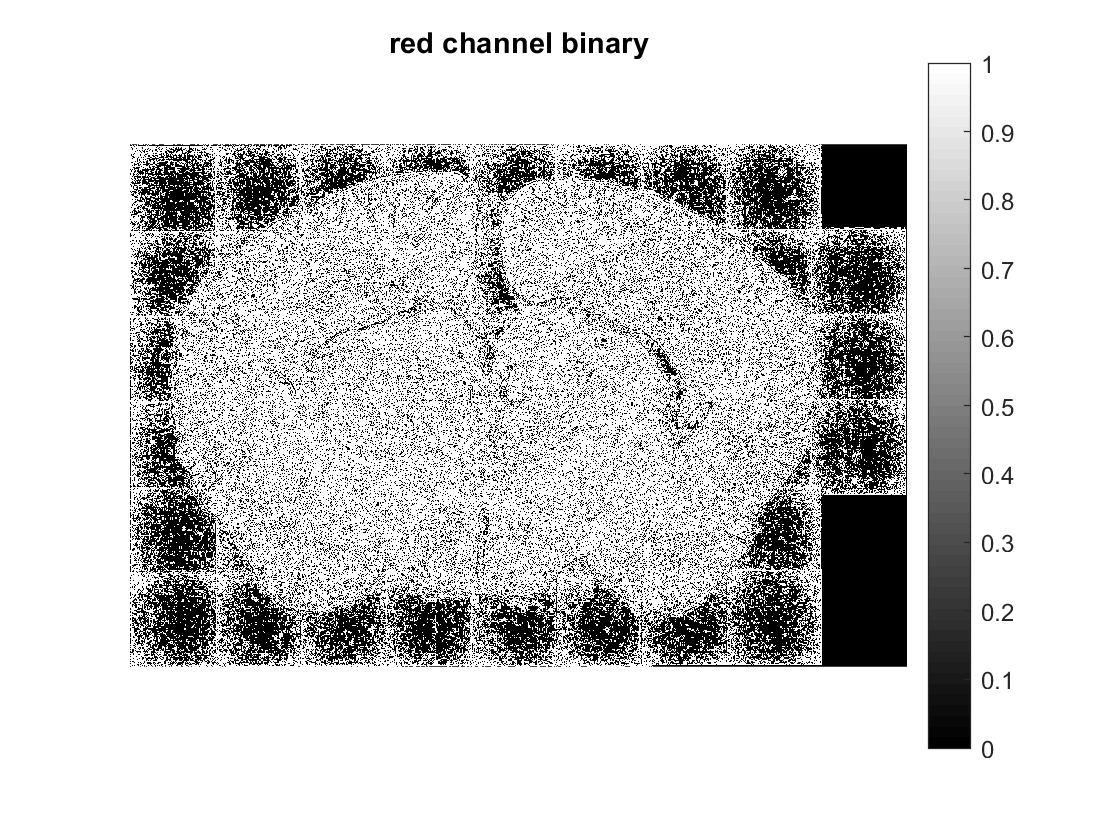

 
     figure(102);
     imagesc(im_red_binary)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('red channel binary')

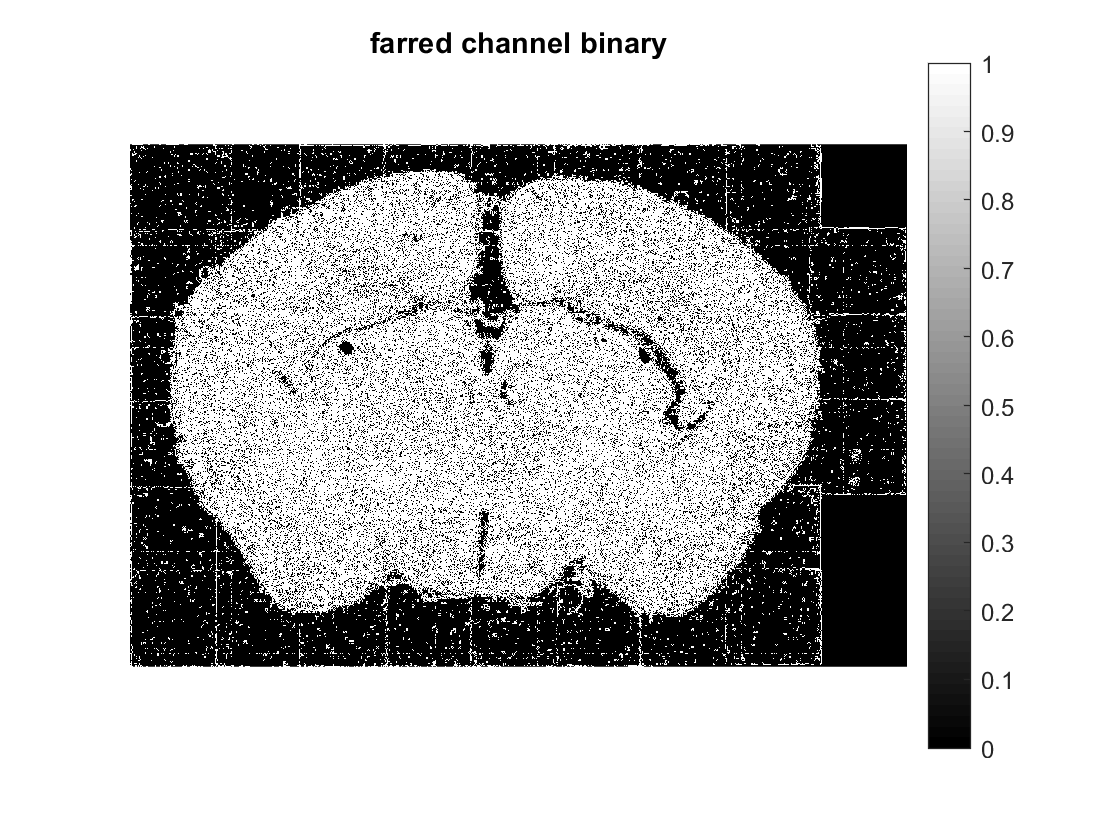

     
     figure(103);
     imagesc(im_farred_binary)
     colormap gray; 
     colorbar
     axis off; axis equal
     title('farred channel binary')

     
 % im_red_binary_16bit =uint16(im_red_binary);
 % im_farred_binary_16bit =uint16(im_farred_binary);

 imwrite(im_red_binary_uint16,[im_dir filesep output_filename_red]);
 imwrite(im_farred_binary_uint16,[im_dir filesep output_filename_farred]);
 
 